img_names =    ["SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
                "plotting_01.jpg"
                "ScatterTableExample_01.jpg"
                "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
                "Test.png"
                "VaryCircleSizeandColorExample_01.jpg"
               ]

img_names = 6×1 string array
    "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
    "plotting_01.jpg"
    "ScatterTableExample_01.jpg"
    "SpecifyLineWidthMarkerSizeAndMarkerColorExample_01.jpg"
    "Test.png"
    "VaryCircleSizeandColorExample_01.jpg"



img_num = 4

img_num = 4

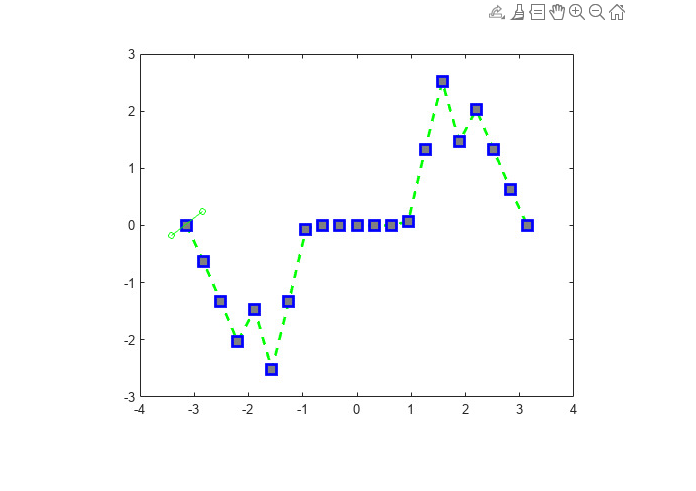

data = struct with fields:
          axes: [2×2 double]
        points: [1×1 struct]
    points_int: [1×1 struct]
         image: [421×561 uint8]
    points_img: [1×1 struct]
    lineformat: 'r.'



data = points_from_img(img_names(img_num), true, false)

% plot of points overlayed
figure(1)
axis ij;

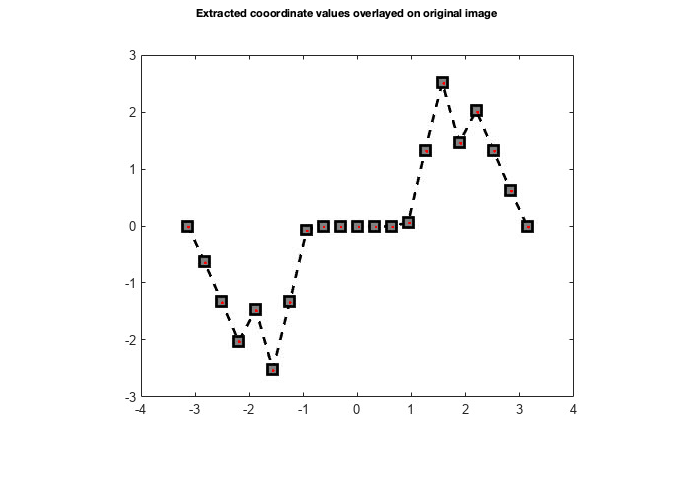

imshow(data.image, []);
title("Extracted cooordinate values overlayed on original image")
hold on;
plot(data.points_img.coords(:,1), data.points_img.coords(:,2), 'r.');

clf("reset") ;

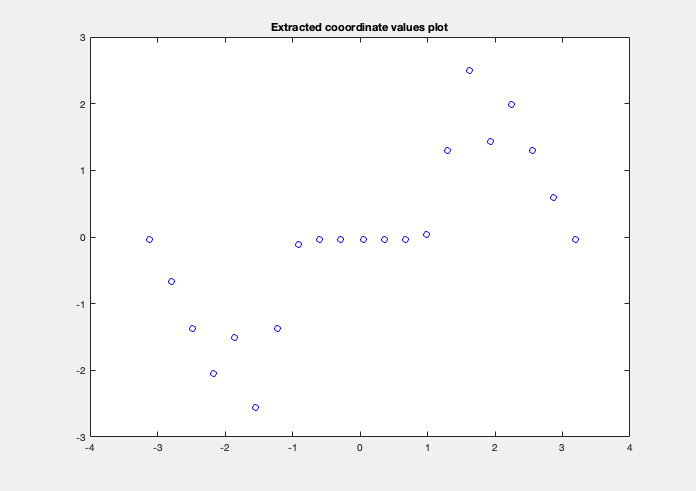

% plot of points
figure(2)
axis xy;
xlim(data.axes(1,:));
ylim(data.axes(2,:));
plot(data.points.coords(:,1), data.points.coords(:,2), 'bo');
title('Extracted cooordinate values plot')

clf("reset");